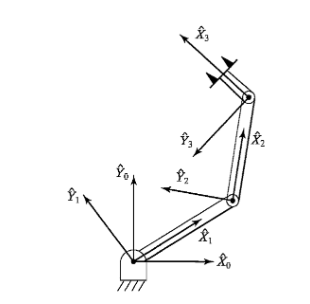

DH Parameters

clear
clc;
L1 = 4;
L2 = 3;
L3 = 2;
m1 = 20;
m2 = 15;
m3 = 10;
I1 = 0.5;
I2 = 0.2;
I3 = 0.1;


Set Geometry of Robot and mass Properties

dhparams = [L1 0 0 0;
        L2 0 0 0;
        L3 0 0 0];

robot = rigidBodyTree;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','revolute');

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');

body1.Joint = jnt1;
body1.Mass = m1;
body1.CenterOfMass = [-L1/2 0 0];
body1.Inertia = [ I1 I1 I1 0 0 0];
body2.Joint = jnt2;
body2.Mass = m2;
body2.CenterOfMass = [-L2/2 0 0];
body2.Inertia = [ I2 I2 I2 0 0 0];
body3.Joint = jnt3;
body3.Mass = m3;
body3.CenterOfMass = [-L3/2 0 0];
body3.Inertia = [ I3 I3 I3 0 0 0];

addBody(robot,body1,'base');
addBody(robot,body2,'body1');
addBody(robot,body3,'body2');


Do The forward dynamics

%Torques
tau1 = 20; %Nm
tau2 = 5;
tau3 = 1;
torques = [tau1 tau2 tau3];
%Initial Joint Positions
q1 = -pi/3; 
q2 = pi/2;
q3 = pi/6;
config = [q1 q2 q3];
%Iniitial Joint Velocities
w1 = 0; %rad/s
w2 = 0;
w3 = 0;
vels = [w1 w2 w3];


robot.DataFormat = 'row';
robot.Gravity = [0 -9.81 0];


No external Forces

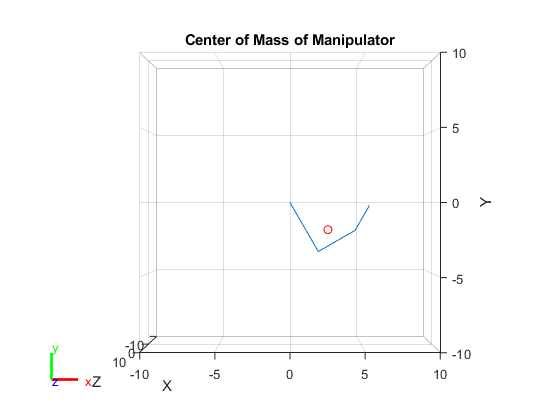

sim_time = 1;
time_step = 0.02;
%show robot initial state
comPos = centerOfMass(robot,config);
figure;
show(robot, config);
hold on
plot3(comPos(1),comPos(2), comPos(3),'or');
hold off
title("Center of Mass of Manipulator");
view(0,90);

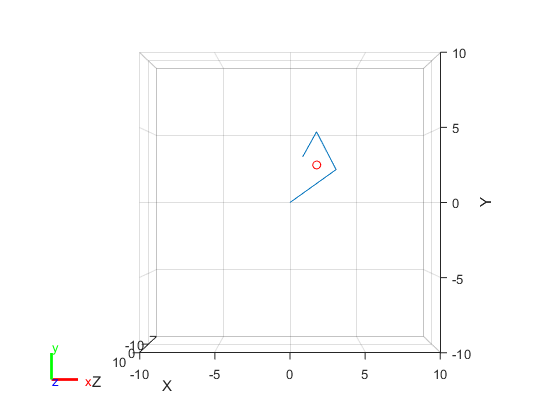


%integrates joint states over time
wrench = [0 0 0 0 0 0];
[a,v,p,t] = integrate_accelerations(robot, config, vels, torques, wrench, time_step, sim_time);

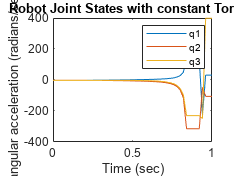

figure;
%plotting the results
plot(t,a);
xlabel("Time (sec)");
ylabel("angular acceleration (radians/sec^2)");
title("Robot Joint States with constant Torque");
legend(["q1","q2","q3"]);

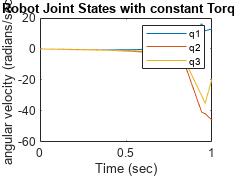

figure;
plot(t,v);
xlabel("Time (sec)");
ylabel("angular velocity (radians/sec)");
title("Robot Joint States with constant Torque");
legend(["q1","q2","q3"]);

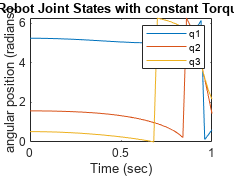

figure
plot(t,p);
xlabel("Time (sec)");
ylabel("angular position (radians)");
title("Robot Joint States with constant Torque");
legend(["q1","q2","q3"]);

With External Forces

sim_time = 1;
time_step = 0.02;
wrench = [0 0 10 10 10 0];
fext = externalForce(robot,'body3',wrench,config);
comPos = centerOfMass(robot,config);
figure;
show(robot, config);
hold on
plot3(comPos(1),comPos(2), comPos(3),'or');
title("Center of Mass of Manipulator");
hold off
view(0,90);

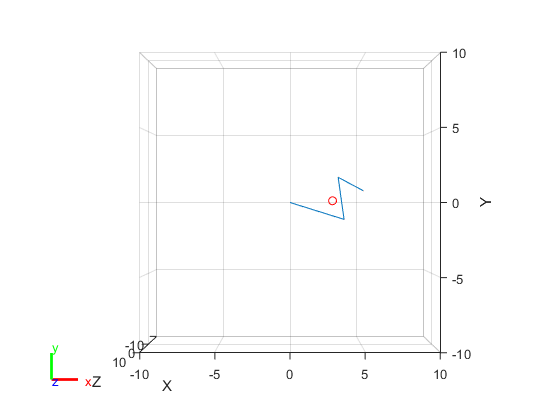

[a,v,p,t] = integrate_accelerations(robot, config, vels, torques, wrench, time_step, sim_time);

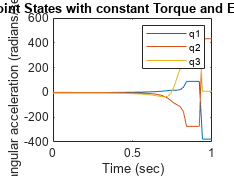

figure;
%plotting the results
plot(t,a);
xlabel("Time (sec)");
ylabel("angular acceleration (radians/sec^2)");
title("Robot Joint States with constant Torque and External Force");
legend(["q1","q2","q3"]);

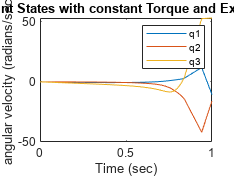

figure;
plot(t,v);
xlabel("Time (sec)");
ylabel("angular velocity (radians/sec)");
title("Robot Joint States with constant Torque and External Force");
legend(["q1","q2","q3"]);

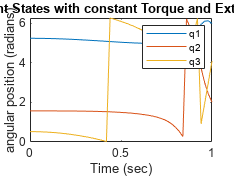

figure
plot(t,p);
xlabel("Time (sec)")
ylabel("angular position (radians)");
title("Robot Joint States with constant Torque and External Force");
legend(["q1","q2","q3"]);

Integration Function

function [acceleration_states,velocity_states,position_states,times] = integrate_accelerations(robot, initial_config, initial_velocity, torques, wrench, time_step, runtime)
    times = 0:time_step:runtime;
    states = length(initial_config);
    position_states = zeros(length(times),states);
    velocity_states = zeros(length(times),states);
    acceleration_states = zeros(length(times),states);
    %sets starting states for t = 0.
    position_states(1,:) = mod(initial_config,2*pi);
    velocity_states(1,:) = initial_velocity;
    external_force = externalForce(robot,'body3',wrench,position_states(1,:));
    acceleration_states(1,:) = forwardDynamics(robot, position_states(1,:), initial_velocity, torques, external_force);
    %integrates with kinematics equations for position and velocity.
    for i = 2:length(times)
        velocity_states(i,:) = velocity_states(i-1,:)+acceleration_states(i-1,:)*time_step;
        position_states(i,:) = mod((position_states(i-1,:)+velocity_states(i-1,:)*time_step+((1/2)*acceleration_states(i-1,:)*time_step^2)),2*pi);
        %adds external force component to dynamics
        external_force = externalForce(robot,'body3',wrench,position_states(1,:));
        acceleration_states(i,:) = forwardDynamics(robot, position_states(i-1,:),velocity_states(i-1,:), torques, external_force);
        %puts an upper bound on acceleration because the dynamic solver
        %would sometimes return massive velocities.
        if (any(abs(acceleration_states(i,:)) > 500))
        acceleration_states(i,:) = acceleration_states(i-1,:);
        end
        show(robot,position_states(i,:));
        comPos = centerOfMass(robot,position_states(i,:));
        hold on
        plot3(comPos(1),comPos(2), comPos(3),'or');
        hold off
        view(0,90);
        pause(0.01);
    end

end